## Typical Switching Energy Losses

- Datos sacados del proporcionado por Infineon para PLECS.

- 1200 V CIPOS™ Maxi CoolSiC™ MOSFET IPM application note    Figure 9

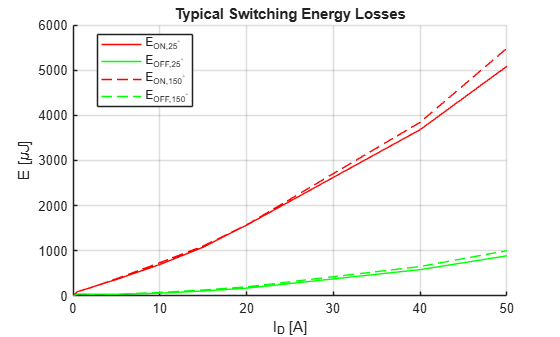

Eonfiltro_25 = (TurnOnLoss.T == 25) & (TurnOnLoss.Vblock == 600);
Eondatos_25 = TurnOnLoss(Eonfiltro_25, :);

Eofffiltro_25 = (TurnOffLoss.T == 25) & (TurnOffLoss.Vblock == 600);
Eoffdatos_25 = TurnOffLoss(Eofffiltro_25, :);

Eonfiltro_150 = (TurnOnLoss.T == 150) & (TurnOnLoss.Vblock == 600);
Eondatos_150 = TurnOnLoss(Eonfiltro_150, :);

Eofffiltro_150 = (TurnOffLoss.T == 150) & (TurnOffLoss.Vblock == 600);
Eoffdatos_150 = TurnOffLoss(Eofffiltro_150, :);

figure;
hold on;
xlim([0; 50]); ylim([0; 6000]);
grid on;
plot(Eondatos_25.Ion, Eondatos_25.Eon_muJ, 'r-', 'DisplayName', "E_{ON,25^\circ}");
plot(Eoffdatos_25.Ion, Eoffdatos_25.Eon_muJ, 'g-', 'DisplayName', "E_{OFF,25^\circ}");
legend("show", 'Location', 'best')

plot(Eondatos_150.Ion, Eondatos_150.Eon_muJ, 'r--', 'DisplayName', "E_{ON,150^\circ}");
plot(Eoffdatos_150.Ion, Eoffdatos_150.Eon_muJ, 'g--', 'DisplayName', "E_{OFF,150^\circ}");

xlabel('I_D [A]'); ylabel('E [\muJ]')
title('Typical Switching Energy Losses')

hold off;

## Output Characteristics

- Datos sacados usando DataTheif.m sobre la figura 2(a) del documento de infineon '1200 V CollSiC MOSFET: Trench technology essentials'

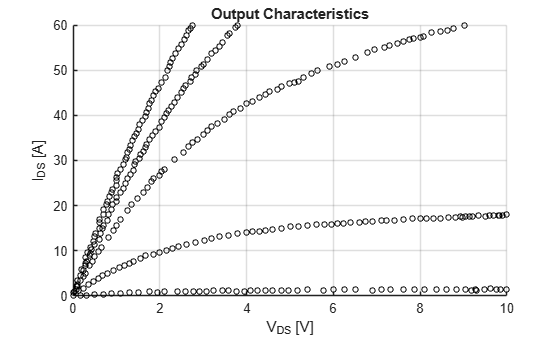

OCVg7 = OutputCharacteristics(OutputCharacteristics.Vg == 7, :);
OCVg10 = OutputCharacteristics(OutputCharacteristics.Vg == 10, :);
OCVg13 = OutputCharacteristics(OutputCharacteristics.Vg == 13, :);
OCVg15 = OutputCharacteristics(OutputCharacteristics.Vg == 15, :);
OCVg17 = OutputCharacteristics(OutputCharacteristics.Vg == 17, :);

figure;
title('Output Characteristics');
xlabel('V_{DS} [V]'); ylabel('I_{DS} [A]');
xlim([0, 10]); ylim([0, 60]);
grid on;

hold on;
plot(OCVg7.Vds, OCVg7.Ids, 'DisplayName', 'V_{GS} = 7', 'Marker', 'o', 'LineStyle', 'none', 'Color', "black", 'MarkerSize', 4);
plot(OCVg10.Vds, OCVg10.Ids, 'DisplayName', 'V_{GS} = 10', 'Marker', 'o', 'LineStyle', 'none', 'Color', "black", 'MarkerSize', 4);
plot(OCVg13.Vds, OCVg13.Ids, 'DisplayName', 'V_{GS} = 13', 'Marker', 'o', 'LineStyle', 'none', 'Color', "black", 'MarkerSize', 4);
plot(OCVg15.Vds, OCVg15.Ids, 'DisplayName', 'V_{GS} = 15', 'Marker', 'o', 'LineStyle', 'none', 'Color', "black", 'MarkerSize', 4);
plot(OCVg17.Vds, OCVg17.Ids, 'DisplayName', 'V_{GS} = 17', 'Marker', 'o', 'LineStyle', 'none', 'Color', "black", 'MarkerSize', 4);
hold off;

## Output Characteristics - Curve Fitter

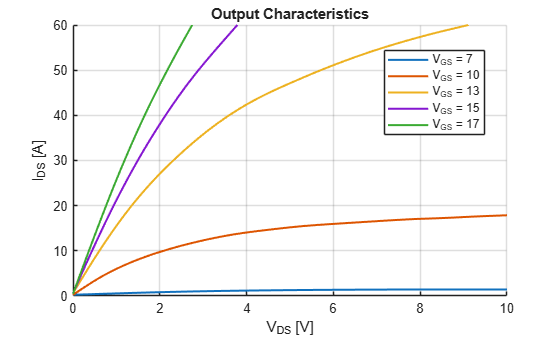

figure;

title('Output Characteristics');
xlim([0, 10]); ylim([0, 60]);
grid on;

hold on;
plot(fittedmodelOCVg7);
plot(fittedmodelOCVg10);
plot(fittedmodelOCVg13);
plot(fittedmodelOCVg15);
plot(fittedmodelOCVg17);
hold off;

xlabel('V_{DS} [V]'); ylabel('I_{DS} [A]');
legend({'V_{GS} = 7', 'V_{GS} = 10', 'V_{GS} = 13', 'V_{GS} = 15', 'V_{GS} = 17'}, 'Location', 'best');

## N-Channel MOSFET 

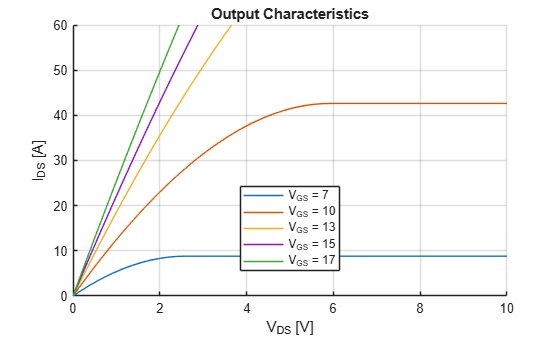

SimulinkVg7 = SimulinkNChannelMOSFET(SimulinkNChannelMOSFET.Vg == 7, :);
SimulinkVg10 = SimulinkNChannelMOSFET(SimulinkNChannelMOSFET.Vg == 10, :);
SimulinkVg13 = SimulinkNChannelMOSFET(SimulinkNChannelMOSFET.Vg == 13, :);
SimulinkVg15 = SimulinkNChannelMOSFET(SimulinkNChannelMOSFET.Vg == 15, :);
SimulinkVg17 = SimulinkNChannelMOSFET(SimulinkNChannelMOSFET.Vg == 17, :);

figure;
title('Output Characteristics');
xlabel('V_{DS} [V]'); ylabel('I_{DS} [A]');
xlim([0, 10]); ylim([0, 60]);
grid on;

hold on;
plot(SimulinkVg7.Vds, SimulinkVg7.Ids);
plot(SimulinkVg10.Vds, SimulinkVg10.Ids);
plot(SimulinkVg13.Vds, SimulinkVg13.Ids);
plot(SimulinkVg15.Vds, SimulinkVg15.Ids);
plot(SimulinkVg17.Vds, SimulinkVg17.Ids);
legend({'V_{GS} = 7', 'V_{GS} = 10', 'V_{GS} = 13', 'V_{GS} = 15', 'V_{GS} = 17'}, 'Location', 'best');
hold off;

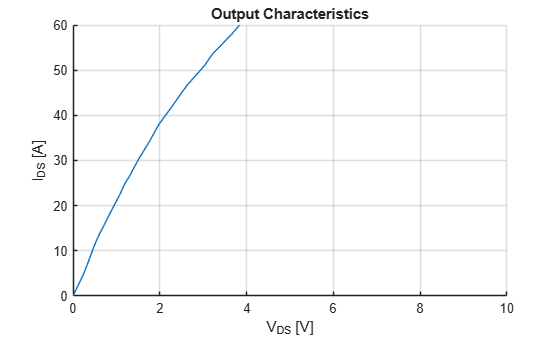

figure;
title('Output Characteristics');
xlabel('V_{DS} [V]'); ylabel('I_{DS} [A]');
xlim([0, 10]); ylim([0, 60]);
grid on;

hold on;
plot(out.Vds, out.Ids)